clear;clc;

origState = rng(17);
msg = randi([0 1],800,1);
%Generate complex signals
cfg4a = lrwpanHRPConfig( ...
    Mode='802.15.4a', ...
    MeanPRF=15.6, ...
    Channel=3, ...
    CodeIndex=6, ...
    PSDULength=length(msg)/8) %#ok<NOPTS>

cfg4a =   lrwpanHRPConfig - 属性:

             Channel: 3
                Mode: '802.15.4a'
             MeanPRF: 15.6000
            DataRate: 0.8500
     SamplesPerPulse: 4
           CodeIndex: 6
     PreambleMeanPRF: 16.1000
    PreambleDuration: 64
             Ranging: 0
          PSDULength: 100

   Read-only properties:
          SampleRate: 1.9968e+09


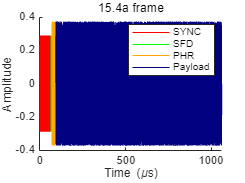

wave4a = lrwpanWaveformGenerator(msg,cfg4a);
%Note: It is a baseband signal.
lrwpanPlotFrame(wave4a,cfg4a);

%HPRF has configuration of samplesPerPulse

info(cfg4a ...
    )

ans = 包含以下字段的 struct :
                    PeakPRF: 499.2000
            BurstsPerSymbol: 32
               NumHopBursts: 8
              ChipsPerBurst: 16
             ChipsPerSymbol: 512
        ConvolutionalCoding: 1
         PreambleCodeLength: 31
    PreambleSpreadingFactor: 16



indices = lrwpanHRPFieldIndices(cfg4a); % length (start/end) of each field
preamble = wave4a( ...
    1:indices.SYNC(end)/cfg4a.PreambleDuration); % 1 of the Nsync repetitions
% plot(preamble)


%这是调制后的载波
channelSpec = [3 4992.8e6 499.2e6];
channelNum = channelSpec(1);
Fc = channelSpec(2);
bw = channelSpec(3);
fprintf('Channel #%d: Center frequency = %.1f MHz, Bandwidth = %.1f MHz.\n', channelNum, Fc/1e6, bw/1e6);

Channel #3: Center frequency = 4992.8 MHz, Bandwidth = 499.2 MHz.


% wave4a=zeros(1,1)

% 定义墙面特性
wall1_position = [5, 0]; % 墙面1位置
wall2_position = [0, 5]; % 墙面2位置
reflection_coefficient = 0.8; % 反射系数

% 定义天线特性
tx_antenna_gain = 2; % 发射天线增益为 2 dB
rx_antenna_gain = 2; % 接收天线增益为 2 dB

% 计算传播路径
rx_position = [0, 0]; 
tx_position = [10,11]; 
% 添加天线阵列
tx_array_length = 3;
rx_array_length = 3;
c =physconst("LightSpeed"); % wavelength (assume)
lambda=c/4992.8e6;
antennaSpacing = lambda / 2;
tx_array_spacing = antennaSpacing;
rx_array_spacing = antennaSpacing;
tx_array_angle = 135; % 发射端天线阵列与水平轴夹角
rx_array_angle = 135; % 接收端天线阵列与水平轴夹角

% 计算天线阵列位置
tx_array_positions = [tx_position-[tx_array_spacing,0];tx_position;tx_position+[tx_array_spacing,0]];
rx_array_positions = [rx_position-[rx_array_spacing,0];rx_position;rx_position+[rx_array_spacing,0]];


% 将天线阵列位置进行旋转
tx_array_positions = rotate_points(tx_array_positions, tx_array_angle, tx_position);
rx_array_positions = rotate_points(rx_array_positions, rx_array_angle, rx_position);

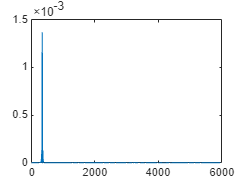

% 旋转函数
function rotated_points = rotate_points(points, angle, center)
    theta = deg2rad(angle);
    rotation_matrix = [cos(theta), -sin(theta); sin(theta), cos(theta)];
    rotated_points = (rotation_matrix * (points' - center') + center')';
end

function [peaksChosen,peaksChosenValue]=findMPC(cir)
    [peaksValue,peaksIdx]=findpeaks(cir);
    %设置阈值
    threshold=0.4*max(abs(cir));
    %找到所有在阈值之上的峰，需要记录峰的索引和峰值
    peaksChosen=peaksIdx(peaksValue>threshold);
    peaksChosenValue=peaksValue(peaksValue>threshold);
end


function cross_corr=CalculateXCorr(preamble,signal)
    % 计算信号的长度
    len1 = length(preamble);
    len2 = length(signal);
    
    % 扩展信号1和信号2，使其长度相等
    maxLen = max(len1, len2);
    signal1 = [preamble; zeros(maxLen - len1,1)];
    signal2 = [signal; zeros(maxLen - len2,1)];
    
    % 对信号1取复共轭
    signal1=flipud(signal1);
    signal2_conj = conj(signal2);
    
    % 计算互相关操作
    cross_corr = ifft(fft(signal2_conj) .* fft(signal1));
end

preamble = wave4a( ...

difference = 1.0e-04 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


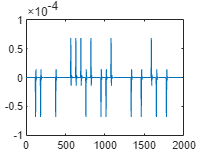

    1:indices.SYNC(end)/cfg4a.PreambleDuration); % 1 of the Nsync repetitions
% plot(preamble)

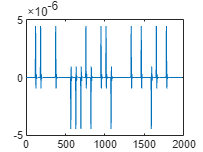


preamble = upsample(preamble,3);

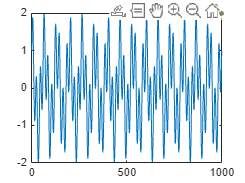

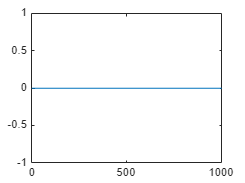

peaksPhase=[];

timestamp=[];
cir_data=[];
received_signals=[];
frequency=4992.8e6;
fs=cfg4a.SampleRate;
peaksInterval=12;
for j=1:1
    rx_position = rx_array_positions(j,:);
    for i=1:1
        tx_position = tx_array_positions(i,:);
        direct_path_distance = norm(rx_position - tx_position); % 直射路径距离
        reflection1_distance = norm(wall1_position - tx_position) + norm(wall1_position - rx_position); % 墙面1反射路径距离
        reflection2_distance = norm(wall2_position - tx_position) + norm(wall2_position - rx_position); % 墙面2反射路径距离
        
        % % 接收信号与发射信号的幅度比
        received_signal_direct=wave4a * lambda / (4*pi*direct_path_distance);
        received_signal_reflection1=wave4a * reflection_coefficient * lambda / (4*pi*reflection1_distance);
        received_signal_reflection2=wave4a * reflection_coefficient * lambda / (4*pi*reflection2_distance);
        
        % % % 接收信号与发射信号的幅度比
        % received_signal_direct=wave4a;
        % received_signal_reflection1=wave4a;
        % received_signal_reflection2=wave4a;
        
        
        % % % 设置更高的采样频率
        % fs = 5 * cfg4a.SampleRate; 
        % % % 得到各个path的多经时延信号，并进行upsampling
        % received_signal_direct = resample(received_signal_direct, fs, cfg4a.SampleRate);
        % received_signal_reflection1 = resample(received_signal_reflection1, fs, cfg4a.SampleRate);
        % received_signal_reflection2 = resample(received_signal_reflection2, fs, cfg4a.SampleRate);
        % % preamble=resample(preamble,fs,cfg4a.SampleRate);
        
        % 定义传播速度（假设与光速相同）
        speed_of_light = physconst("Lightspeed");
        
        % 计算传播时延
        direct_path_delay = direct_path_distance / speed_of_light; % 直射路径时延（秒）
        reflection1_delay = reflection1_distance / speed_of_light;% 反射路径1时延（秒）
        reflection2_delay = reflection2_distance / speed_of_light; % 反射路径2时延（秒）
        
        
        
        %得到各个path的多经时延信号
        received_signal_direct_delayed = [zeros(round(direct_path_delay * fs),1) ;received_signal_direct];
        received_signal_reflection1_delayed = [zeros(round(reflection1_delay * fs),1) ;received_signal_reflection1];
        received_signal_reflection2_delayed = [zeros(round(reflection2_delay * fs),1); received_signal_reflection2];
        
        len1 = length(received_signal_direct_delayed);
        len2 = length(received_signal_reflection1_delayed);
        len3 = length(received_signal_reflection2_delayed);
        maxLen = max(len1,len2);
        maxLen =max(maxLen,len3);
        received_signal_direct_delayed = [received_signal_direct_delayed; zeros(maxLen - len1,1)];
        received_signal_reflection1_delayed = [received_signal_reflection1_delayed; zeros(maxLen - len2,1)];
        received_signal_reflection2_delayed=[received_signal_reflection2_delayed; zeros(maxLen - len3,1)];
        
        
        % Calculate the phase shift for each path
        direct_path_phase_shift = exp(-1j * 2 * pi * direct_path_distance / lambda);
        reflection1_phase_shift = exp(-1j * 2 * pi * reflection1_distance / lambda);
        reflection2_phase_shift = exp(-1j * 2 * pi * reflection2_distance / lambda);
        
        % Apply phase shifts to received signals
        received_signal_direct_phase = received_signal_direct_delayed .* direct_path_phase_shift;
        received_signal_reflection1_phase = received_signal_reflection1_delayed .* reflection1_phase_shift;
        received_signal_reflection2_phase = received_signal_reflection2_delayed .* reflection2_phase_shift;
        
        
        % % 组合多径时延后的信号
        % received_signal_total = received_signal_direct_phase + ...
        %     received_signal_reflection1_phase + received_signal_reflection2_phase;
          received_signal_total = received_signal_direct_delayed + ...
            received_signal_reflection1_delayed + received_signal_reflection2_delayed;
        

        % 添加噪声
        noise_power = -80; % 噪声功率为 -80 dBm
        noise = awgn(zeros(size(received_signal_total)), noise_power, 'measured'); % 生成高斯白噪声
        
        %最终信号
        % received_signal = received_signal_reflection2_phase + noise;
        received_signal = received_signal_reflection1_delayed+received_signal_reflection2_delayed+ noise ;

        received_signal = upsample(received_signal,3);
        % received_signals=[received_signals;received_signal'];
        % received_signal = received_signal_reflection1_delayed +received_signal_reflection2_delayed+ noise;

        % receivedCorrelation1=CalculateXCorr(preamble,received_signal_reflection1_delayed);
        % reshaped_correlation1 = reshape(receivedCorrelation1(1:indices.SYNC(end)), [], cfg4a.PreambleDuration);
        % % 对每列求平均
        % average_correlation1 = mean(reshaped_correlation1, 2);
        % abs_correlation1=abs(average_correlation1);
        % figure;
        % plot(real(average_correlation1));

        
        % receivedCorrelation2=CalculateXCorr(preamble,received_signal_reflection2_delayed);
        % reshaped_correlation2 = reshape(receivedCorrelation2(1:indices.SYNC(end)), [], cfg4a.PreambleDuration);
        % % 对每列求平均
        % average_correlation2 = mean(reshaped_correlation2, 2);
        % % abs_correlation2=abs(average_correlation2);
        % figure;
        % plot(real(average_correlation2));


        receivedCorrelation=CalculateXCorr(preamble,received_signal);
        reshaped_correlation = reshape(receivedCorrelation(1:indices.SYNC(end)*3), [], cfg4a.PreambleDuration);
        % 对每列求平均
        average_correlation = mean(reshaped_correlation, 2);
        abs_correlation=abs(average_correlation);
        figure;
        plot(abs_correlation);

        % plot(imag(average_correlation));

        [peaksChosen,peaksChosenValue]=findMPC(abs_correlation);
        phases=receivedCorrelation(peaksChosen);
        peaksPhase=[peaksPhase;phases(1:end)'];
        timestamp=[timestamp;peaksChosen'*1e9 / fs];
    end
end

difference=received_signals(3,:)-received_signals(2,:)
figure;
plot(real(difference(1:1984)));
figure;
plot(imag(difference(1:1984)))
